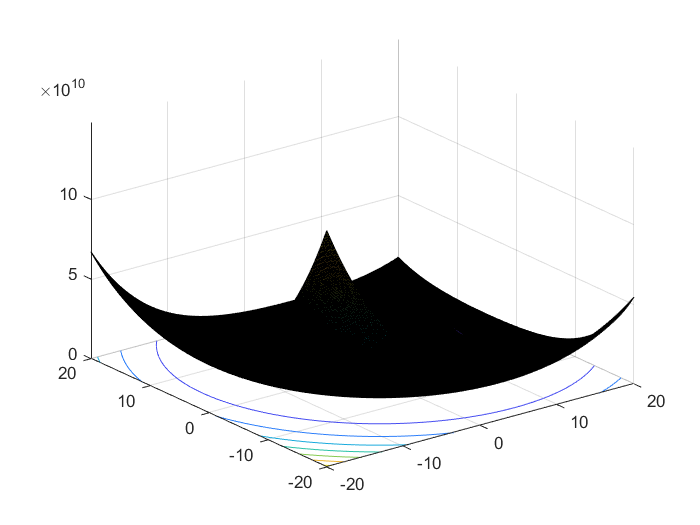

x = (-20:0.1:20);
y= (-20:0.1:20);
[X,Y] = meshgrid(x,y);
f = penaltyF(X,Y);
surfc(X,Y,f)

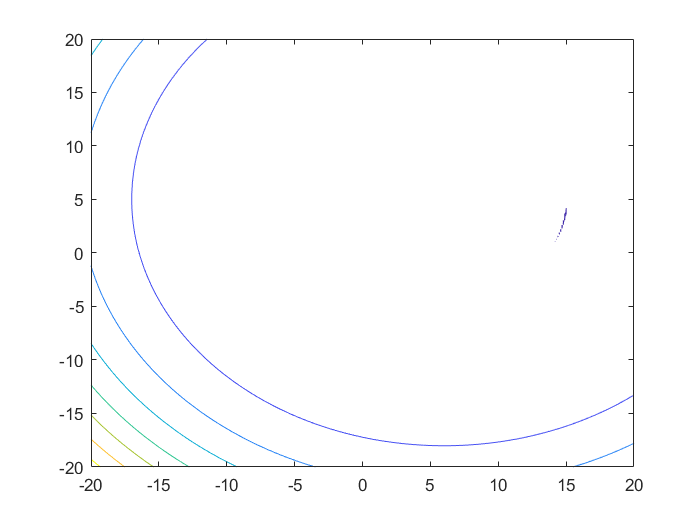

contour(X,Y,f)

options = optimoptions(@fminunc,'Algorithm','Quasi-Newton','GradObj','on','MaxIter',400);
[opt,optval] = fminunc(@(t)costFunction(t),[10,10]',options)


Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


opt =    14.0892
    0.8309


optval = -6.9686e+03

function value = penaltyF(x,y)
value = zeros(length(x),1);
f = @(x,y) (x-10).^3+(y-20).^3;
gtr1 = @(x,y) (x-5).^2+(y-5).^2-100;
gtr2 = @(x,y) (x-13);
gtr3 = @(x,y) (y-0);

lwr1 = @(x,y) (x-6).^2+(y-5).^2-82.81;
lwr2 = @(x,y) (x-20);
lwr3 = @(x,y) (y-4);
R = 100000;

violation1 = gtr1(x,y)<0;
violation2 = gtr2(x,y)<0;
violation3 = gtr3(x,y)<0;

violation4 = lwr1(x,y)>0;
violation5 = lwr2(x,y)>0;
violation6 = lwr3(x,y)>0;

value = value +f(x,y) +R.*(violation1.*gtr1(x,y).^2+violation2.*gtr2(x,y).^2+violation3.*gtr3(x,y).^2+violation4.*lwr1(x,y).^2+violation5.*lwr2(x,y).^2+violation6.*lwr3(x,y).^2);

end

function [value,gradient] = costFunction(x)
delta = 10^-4;
value = penaltyF(x(1),x(2));
gradient = zeros(2,1);
gradient(1) = (penaltyF(x(1)+delta,x(2))-penaltyF(x(1)-delta,x(2)))/(2*delta);
gradient(2) = (penaltyF(x(1),x(2)+delta)-penaltyF(x(1),x(2)-delta))/(2*delta);
end